clc; clear; close all;

code

a=1;
b=0.1;
c=1;
p=[a b c];
roots(p)

ans =   -0.0500 + 0.9987i
  -0.0500 - 0.9987i



EDO resolvida:
1*y'' + 0.1*y' + 1*y = F(t)

Condições iniciais:
y(0) = 1
y'(0) = 0



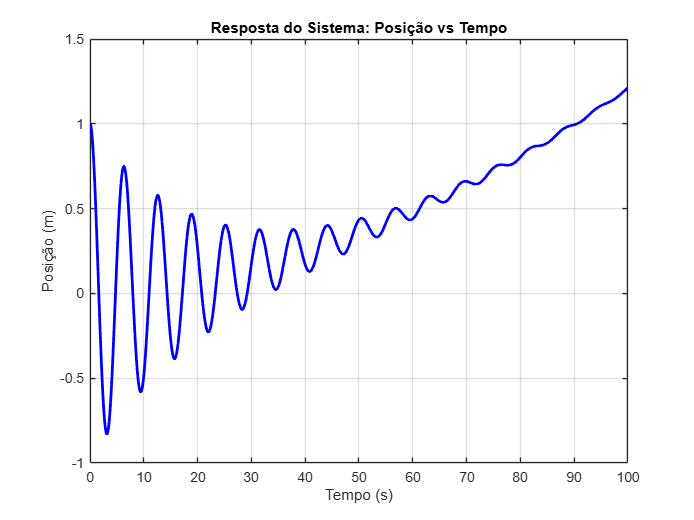

ans =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009



y0 = 1;
v0 = 0;

t = 0:0.0001:100;

X = @(t) 0.0001*t^2+0.002*t+0.01;
solve_edo_2ordem(a,b,c,y0,v0,X,t)

gabs

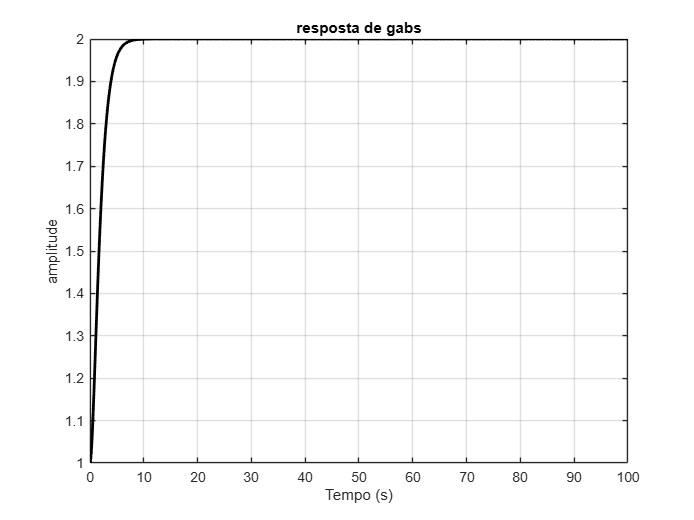

% Plot adicional da força aplicada
gabs = -1*exp(-1*t)-1*t.*exp(-1*t)+2;
plot(t, gabs, 'k-', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('amplitude');
title('resposta de gabs');
grid on;
hold off

Frequencia natural

Wn=(c/a)^(1/2)

Wn = 1

Atenuação

sigma=(b*Wn)/2

sigma = 0.0500

Frequencia nat. amortecida

Wd=(Wn^2-sigma^2)^(1/2)

Wd = 0.9987